# Trabajo grupal 1 (Métodos Numéricos)

- Sección: 9

- N° de grupo: 3

- Integrante 1 (líder):  Maxwell Lupo Gregorio Collazos Solis  (100%)

- Integrante 2:

- Integrante 3:

- Integrante 4:

- Integrante 5:

**Observación:** No olvidar añadir el porcentaje de participación.

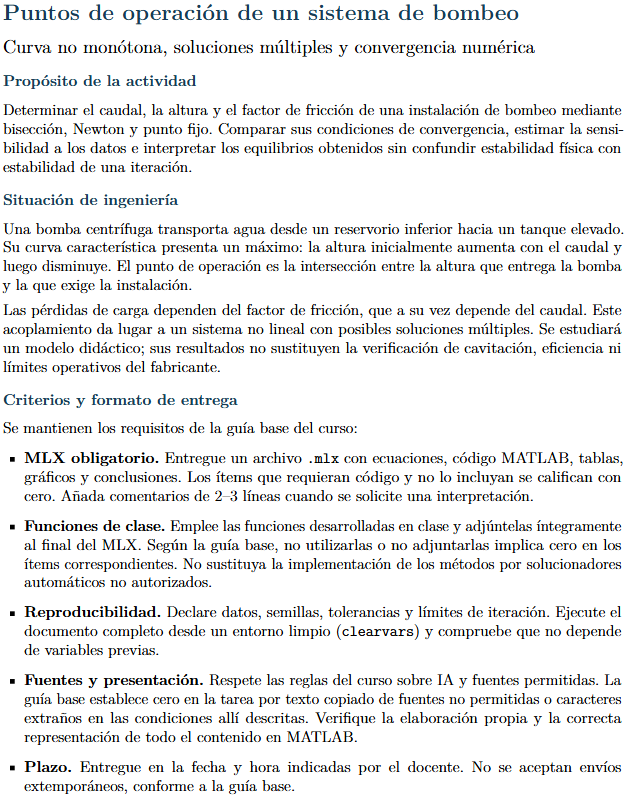

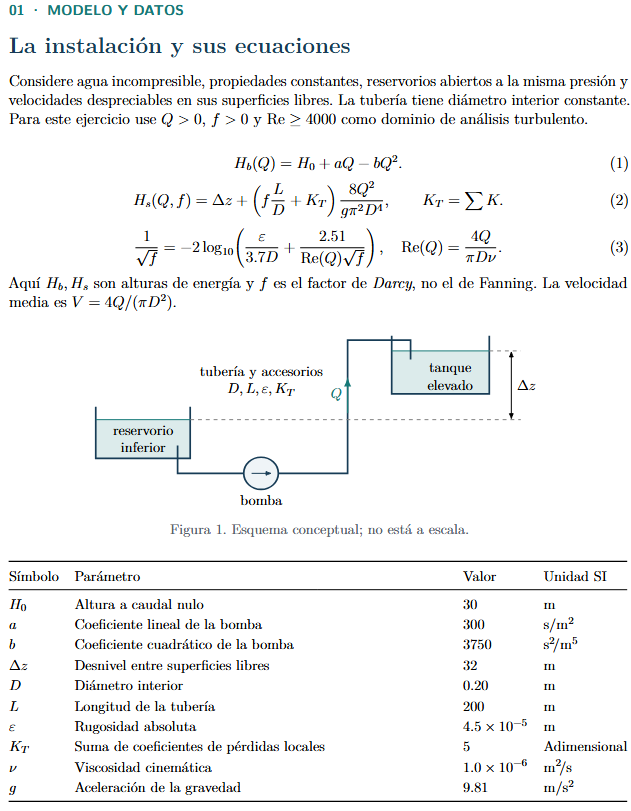

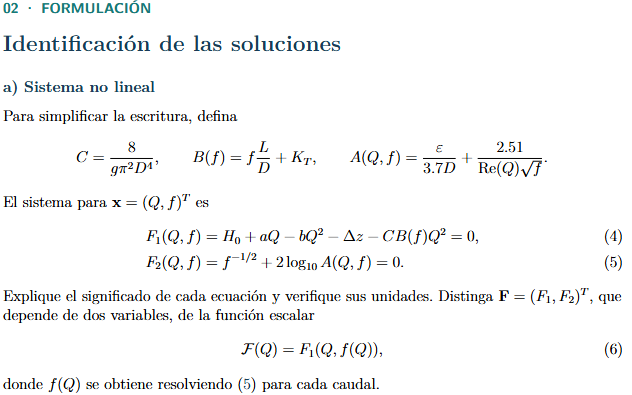

%Inserte aqui su codigo
H0 = 30;                   % m      - Altura a caudal nulo
a  = 300;                  % s/m^2  - Coeficiente lineal de la bomba
b  = 3750;                 % s^2/m^5- Coeficiente cuadratico de la bomba
% Geometria y propiedades del sistema
delta_z = 32;              % m      - Desnivel entre superficies libres
D = 0.20;                  % m      - Diametro interior de la tuberia
L = 200;                   % m      - Longitud de la tuberia
eps = 4.5e-5;              % m      - Rugosidad absoluta
K_T = 5;                   % adim   - Suma de coeficientes de perdidas locales
nu = 1.0e-6;               % m^2/s  - Viscosidad cinematica del agua
g = 9.81;                  % m/s^2  - Aceleracion de la gravedad





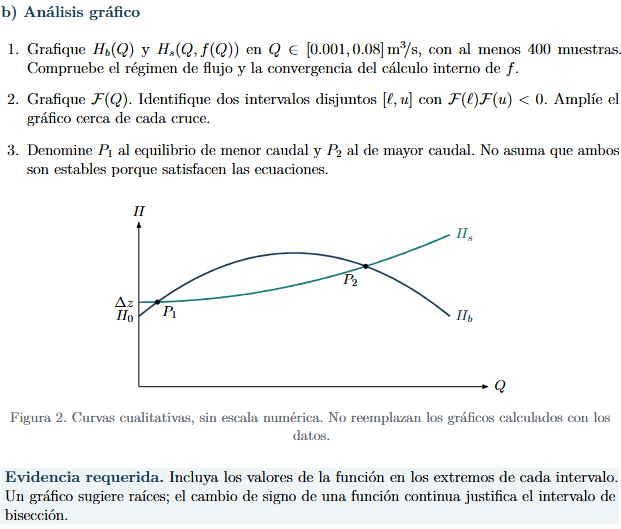

### a)


%Inserte aqui su codigo

C = 8 / (g * pi^2 * D^4);

%Funcoines auxiliares
B_func = @(f) f * (L/D) + K_T;
A_func = @(Q, f) eps/(3.7*D) + 2.51/(4*Q/(pi*D*nu) * sqrt(f));

% Definicion de F1 y F2
F1_func = @(Q, f) H0 + a*Q - b*Q.^2 - delta_z - C*B_func(f)*Q.^2;
F2_func = @(Q, f) 1/sqrt(f) + 2*log10(A_func(Q, f));

Se define el sistema F = (F1, F2)^T, que depende de dos variables (Q, f):

- F1  es la ecuacion de energia: iguala la altura que entrega la bomba con la altura que exige la instalacion. Cada termino esta en metros [m].

- F2 Es la ecuacion de Colebrook-White, que define el factor de friccion f   de forma implicita. Es adimensional.

F = (F1,F2)^T depende de DOS variables (Q y f), mientras la funcion escalar F(Q) = F1(Q, f(Q)) depende de una sola variable. En F(Q), el valor de f no es libre, para cada Q se obtiene resolviendo F2(Q,f) = 0 de forma interna. Por eso F(Q) es util para graficar y localizar raices, mientras que F1 y F2 por separado describen el sistema acoplado completo.

**C e**s una constante que no depende del caudal (Q) ni del factor de fricción (f). Agrupa los parámetros geométricos y físicos fijos que convierten el caudal al cuadrado en una pérdida de altura por velocidad.

**B(f) r**epresenta la resistencia total al flujo: la fricción distribuida a lo largo de la tubería más las pérdidas locales por accesorios (K_T). Depende únicamente de f.

**A(Q, f) e**s el argumento del logaritmo en la ecuación de Colebrook-White. Combina el efecto de la rugosidad relativa de la tubería (\varepsilon / (3.7 \cdot D)) con el efecto del régimen de flujo a través del número de Reynolds  Re(Q). Depende tanto de Q como de f.

### b)

####     b.1)

    Se grafican Hb(Q) y Hs(Q,f(Q)) en Q en [0.001, 0.08] m3/s, con 500 muestras. Para cada Q se resuelve F2(Q,f) = 0         mediante punto fijo, con semilla f0 = 0.02 y tolerancia 1e-10, verificando que el caudal se encuentre en regimen turbulento (Re >= 4000).

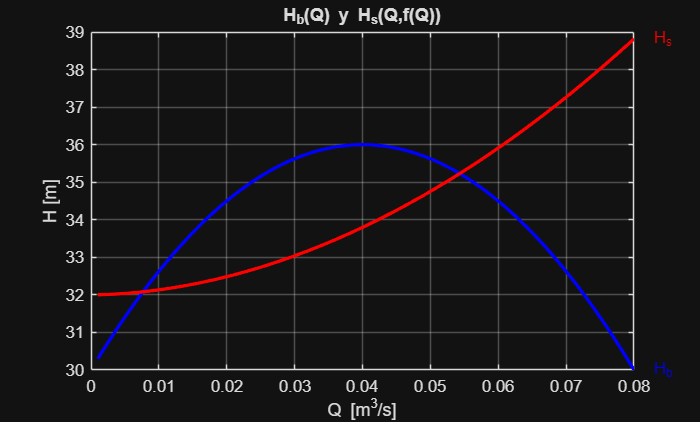

Q_vec = linspace(0.001, 0.08, 500);
Re_vec = 4*Q_vec/(pi*D*nu);
f_vec = zeros(size(Q_vec));
conv_vec = false(size(Q_vec));

for i = 1:length(Q_vec)
    if Re_vec(i) < 4000          % fuera de regimen turbulento
        f_vec(i) = NaN;
        continue
    end
    f_k = 0.02;
    for iter = 1:100
        A_val = A_func(Q_vec(i), f_k);
        if A_val <= 0 || A_val >= 1
            f_k = NaN; break
        end
        f_k_new = 1 / (-2*log10(A_val))^2;
        if abs(f_k_new - f_k)/max(abs(f_k_new),1e-12) <= 1e-10
            f_k = f_k_new; conv_vec(i) = true; break
        end
        f_k = f_k_new;
    end
    f_vec(i) = f_k;
end


regimen_ok = all(Re_vec >= 4000);       
convergio_ok = all(conv_vec);            

Hb_vec = H0 + a*Q_vec - b*Q_vec.^2;
Hs_vec = delta_z + C*B_func(f_vec).*Q_vec.^2;

figure;
plot(Q_vec, Hb_vec, 'b', 'LineWidth', 2);
hold on;
plot(Q_vec, Hs_vec, 'r', 'LineWidth', 2);
text(Q_vec(end), Hb_vec(end), '  H_b', 'Color', 'b');
text(Q_vec(end), Hs_vec(end), '  H_s', 'Color', 'r');
title('H_b(Q) y H_s(Q,f(Q))');
xlabel('Q [m^3/s]');
ylabel('H [m]');
grid on;

####     b.2)

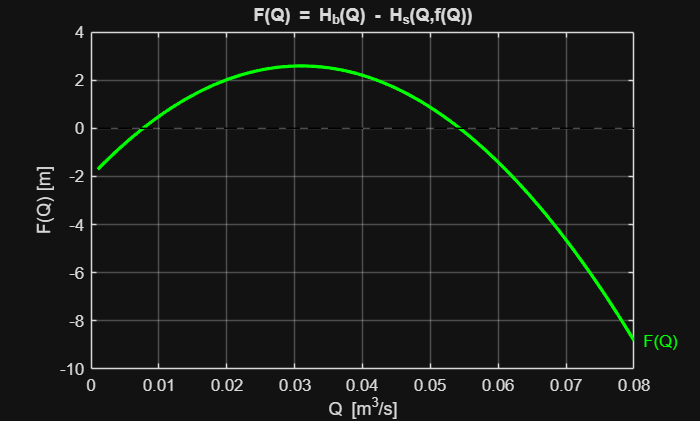

F_vec = Hb_vec - Hs_vec;

figure;
plot(Q_vec, F_vec, 'g', 'LineWidth', 2);
hold on;
plot(Q_vec, zeros(size(Q_vec)), 'k--');
text(Q_vec(end), F_vec(end), '  F(Q)', 'Color', 'g');
title('F(Q) = H_b(Q) - H_s(Q,f(Q))');
xlabel('Q [m^3/s]');
ylabel('F(Q) [m]');
grid on;


Q_clean = Q_vec(~isnan(F_vec));
F_clean = F_vec(~isnan(F_vec));
cambios = diff(sign(F_clean));
idx_cambios = find(cambios ~= 0);

n_intervalos = 0;
for k = 1:length(idx_cambios)
    idx = idx_cambios(k);
    if F_clean(idx) * F_clean(idx+1) < 0
        n_intervalos = n_intervalos + 1;
        if n_intervalos == 1
            interval_1 = [Q_clean(idx), Q_clean(idx+1)];
        elseif n_intervalos == 2
            interval_2 = [Q_clean(idx), Q_clean(idx+1)];
        end
    end
end


% Se incluyen los valores de F(Q) en los extremos de cada intervalo.
% Un grafico sugiere raices; el cambio de signo de una funcion continua
% (F(l)*F(u) < 0) es lo que justifica el intervalo de biseccion.

% F en los extremos de cada intervalo
F1_izq = interp1(Q_vec, F_vec, interval_1(1));
F1_der = interp1(Q_vec, F_vec, interval_1(2));
F2_izq = interp1(Q_vec, F_vec, interval_2(1));
F2_der = interp1(Q_vec, F_vec, interval_2(2));

evidencia = table([interval_1(1); interval_1(2); interval_2(1); interval_2(2)], ...
                   [F1_izq; F1_der; F2_izq; F2_der], ...
                   'VariableNames', {'Q', 'F_de_Q'})

evidencia = 4×2 table
        Q          F_de_Q  
    _________    __________

    0.0076493    -0.0055787
    0.0078076       0.02963
     0.054194      0.028801
     0.054353    -0.0062295


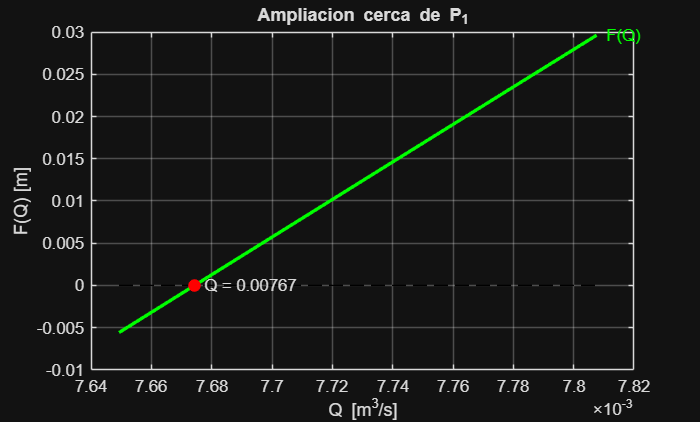


% b.2) Ampliacion cerca de P1 (con punto de cruce marcado)
Q_zoom1 = linspace(interval_1(1), interval_1(2), 150);
f_zoom1 = interp1(Q_vec(~isnan(F_vec)), f_vec(~isnan(F_vec)), Q_zoom1);
F_zoom1 = (H0 + a*Q_zoom1 - b*Q_zoom1.^2) - (delta_z + C*B_func(f_zoom1).*Q_zoom1.^2);

% Interpolacion lineal para ubicar el cruce F(Q)=0 dentro del intervalo
Q_cruce1 = interval_1(1) - F1_izq*(interval_1(2)-interval_1(1))/(F1_der-F1_izq);

figure;
plot(Q_zoom1, F_zoom1, 'g', 'LineWidth', 2);
hold on;
plot(Q_zoom1, zeros(size(Q_zoom1)), 'k--');
plot(Q_cruce1, 0, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 7);
text(Q_cruce1, 0, sprintf('  Q = %.5f', Q_cruce1));
text(Q_zoom1(end), F_zoom1(end), '  F(Q)', 'Color', 'g');
title('Ampliacion cerca de P_1');
xlabel('Q [m^3/s]');
ylabel('F(Q) [m]');
grid on;

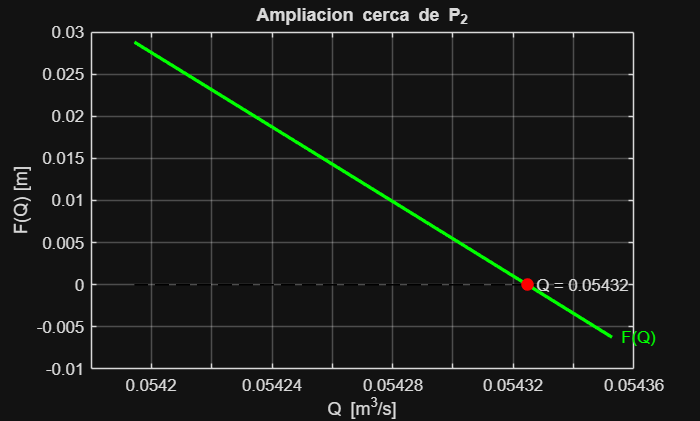


%% [CODIGO] b.2) Ampliacion cerca de P2 (con punto de cruce marcado)
Q_zoom2 = linspace(interval_2(1), interval_2(2), 150);
f_zoom2 = interp1(Q_vec(~isnan(F_vec)), f_vec(~isnan(F_vec)), Q_zoom2);
F_zoom2 = (H0 + a*Q_zoom2 - b*Q_zoom2.^2) - (delta_z + C*B_func(f_zoom2).*Q_zoom2.^2);

Q_cruce2 = interval_2(1) - F2_izq*(interval_2(2)-interval_2(1))/(F2_der-F2_izq);

figure;
plot(Q_zoom2, F_zoom2, 'g', 'LineWidth', 2);
hold on;
plot(Q_zoom2, zeros(size(Q_zoom2)), 'k--');
plot(Q_cruce2, 0, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 7);
text(Q_cruce2, 0, sprintf('  Q = %.5f', Q_cruce2));
text(Q_zoom2(end), F_zoom2(end), '  F(Q)', 'Color', 'g');
title('Ampliacion cerca de P_2');
xlabel('Q [m^3/s]');
ylabel('F(Q) [m]');
grid on;

####     b.3)

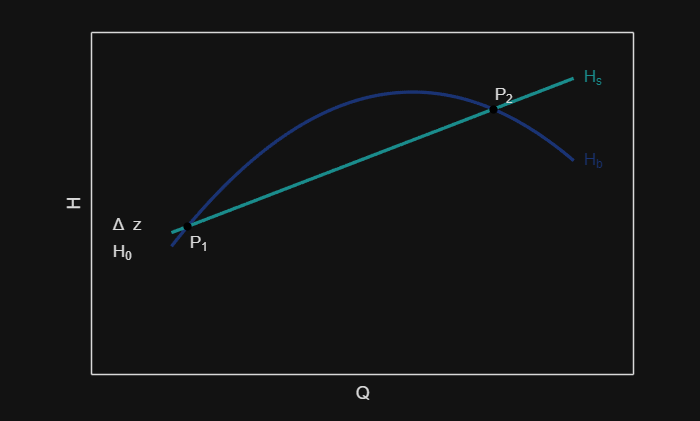

Q_qual = linspace(0, 10, 200);

% H0_qual y dz_qual: Hs empieza un poco por encima de Hb, igual que en
% los datos reales (Delta_z=32 > H0=30), para que existan dos cruces.
H0_qual = 3;
dz_qual = 3.32;

Hb_qual = H0_qual + 1.2*Q_qual - 0.1*Q_qual.^2;   
Hs_qual = dz_qual + 0.36*Q_qual;                   

% Cruces reales de estas dos curvas (calculados a mano): Q=0.4 y Q=8.0
Q_P1 = 0.4;  H_P1 = H0_qual + 1.2*Q_P1 - 0.1*Q_P1^2;
Q_P2 = 8.0;  H_P2 = H0_qual + 1.2*Q_P2 - 0.1*Q_P2^2;

figure;
plot(Q_qual, Hb_qual, 'Color', [0.10 0.20 0.45], 'LineWidth', 2);
hold on;
plot(Q_qual, Hs_qual, 'Color', [0.10 0.55 0.55], 'LineWidth', 2);

plot(Q_P1, H_P1, 'k.', 'MarkerSize', 15);
plot(Q_P2, H_P2, 'k.', 'MarkerSize', 15);
text(Q_P1, H_P1-0.4, 'P_1');
text(Q_P2, H_P2+0.3, 'P_2');

text(Q_qual(end)+0.2, Hb_qual(end), 'H_b', 'Color', [0.10 0.20 0.45]);
text(Q_qual(end)+0.2, Hs_qual(end), 'H_s', 'Color', [0.10 0.55 0.55]);

text(-1.5, dz_qual+0.15, '\Delta z');
text(-1.5, H0_qual-0.15, 'H_0');

xlabel('Q');
ylabel('H');
xlim([-2, 11.5]);
ylim([0, 8]);
set(gca, 'XTick', [], 'YTick', []);

% Valores de F(Q) en los extremos de cada intervalo. El cambio de
% signo de una funcion continua justifica el intervalo de biseccion.

% F en los extremos de cada intervalo
F1_izq = interp1(Q_vec, F_vec, interval_1(1));
F1_der = interp1(Q_vec, F_vec, interval_1(2));
F2_izq = interp1(Q_vec, F_vec, interval_2(1));
F2_der = interp1(Q_vec, F_vec, interval_2(2));

evidencia = table([interval_1(1); interval_1(2); interval_2(1); interval_2(2)], ...
                   [F1_izq; F1_der; F2_izq; F2_der], ...
                   'VariableNames', {'Q', 'F_de_Q'})

evidencia = 4×2 table
        Q          F_de_Q  
    _________    __________

    0.0076493    -0.0055787
    0.0078076       0.02963
     0.054194      0.028801
     0.054353    -0.0062295


- **Intervalo 1** (filas 1 y 2): F pasa de **−0.0056** a **+0.0296**  sí cambia de signo 

- **Intervalo 2** (filas 3 y 4): F pasa de **+0.0288** a **−0.0062**  sí cambia de signo 

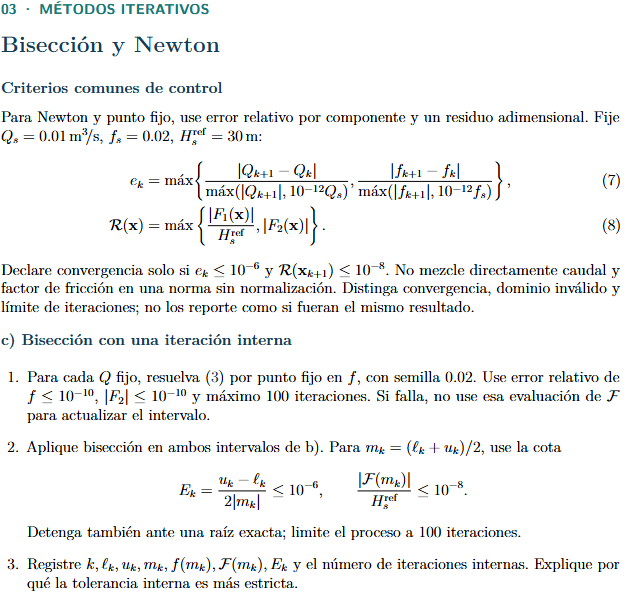

%Inserte Aqui su codigo

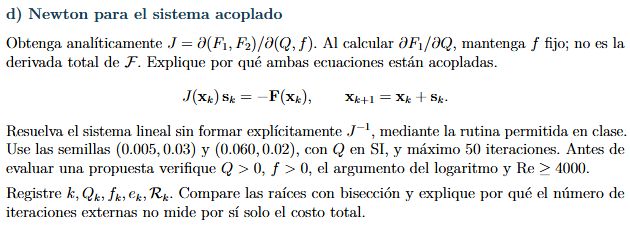

%Inserte Aqui su codigo

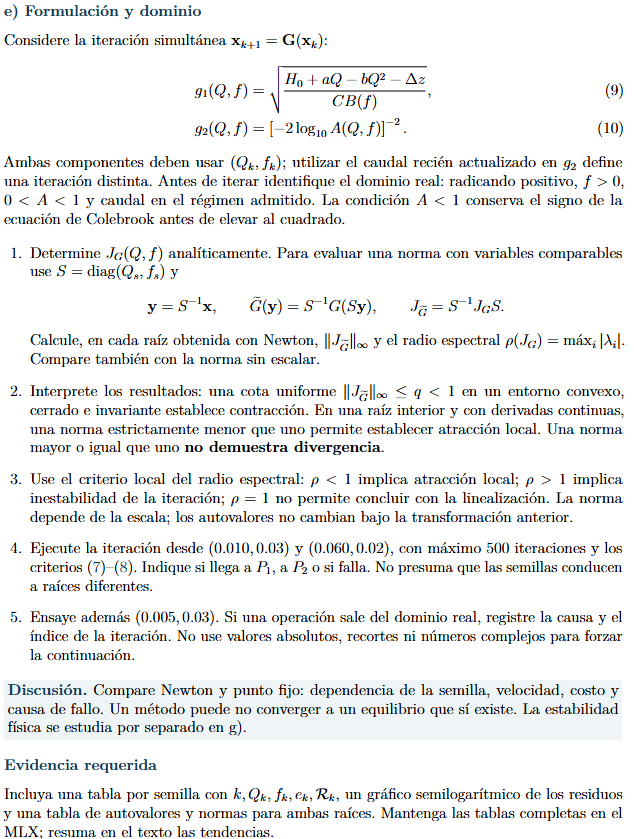

%Inserte aqui su codigo

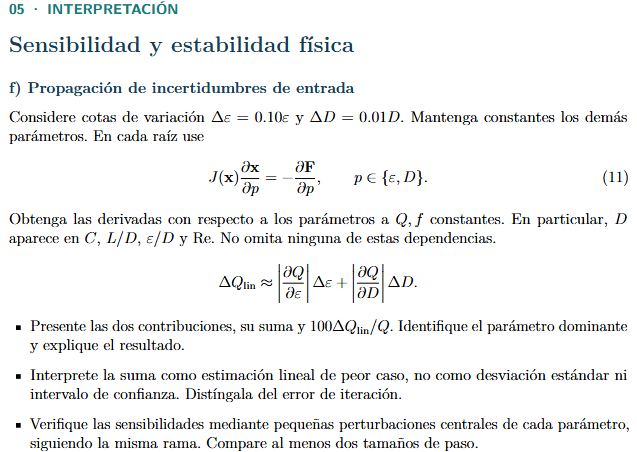

%Inserte aqui su codigo

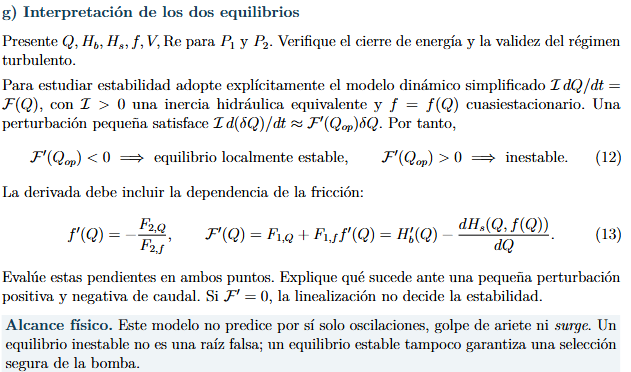

%Inserte aqui su codigo

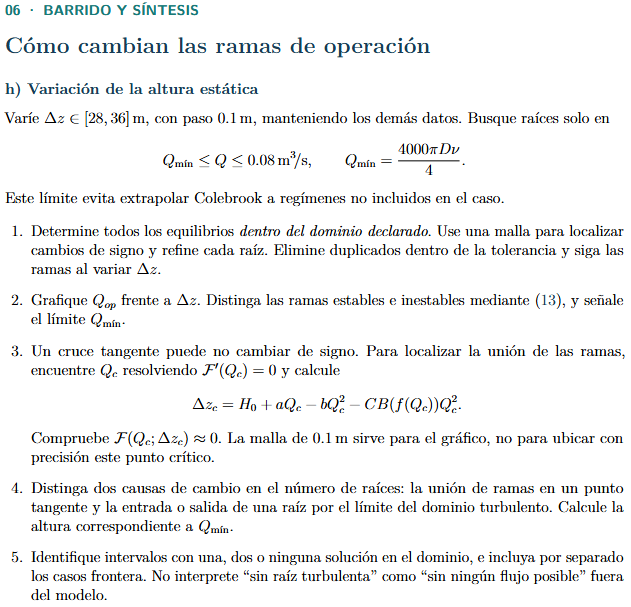

%Inserte aqui su codigo